clc;clear;close all;


## A

syms t x(t) [4 1]
syms T(t) rho CD_a u(t) S m(t) g theta(t) alpha(t)
theta(t)==u(t)

$$ans = \theta \left(t\right)=u\left(t\right)$$

assume(t>0)
assume(t<=60)
assume(m(t)>0)
a=diff(x)==[x3;x4;
         (T-0.5*rho*(x3^2+x4^2)*S*CD_a*(u(t)-atan(x4/x3)))/m(t)*cos(u(t));
         (T-0.5*rho*(x3^2+x4^2)*S*CD_a*(u(t)-atan(x4/x3)))/m(t)*sin(u(t))-g]

$$a(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{3}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=x_{4}\left(t\right)\\ \frac{\partial }{\partial t}x_{3}\left(t\right)=\frac{\cos\left(u\left(t\right)\right)\,\left(T\left(t\right)-0.5000\,{\mathrm{CD}}_{a}\,S\,\rho \,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}\\ \frac{\partial }{\partial t}x_{4}\left(t\right)=\frac{\sin\left(u\left(t\right)\right)\,\left(T\left(t\right)-0.5000\,{\mathrm{CD}}_{a}\,S\,\rho \,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-g \end{array}\right)$$

b=rhs(a)

$$b(t) = \left(\begin{array}{c} x_{3}\left(t\right)\\ x_{4}\left(t\right)\\ \frac{\cos\left(u\left(t\right)\right)\,\left(T\left(t\right)-0.5000\,{\mathrm{CD}}_{a}\,S\,\rho \,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}\\ \frac{\sin\left(u\left(t\right)\right)\,\left(T\left(t\right)-0.5000\,{\mathrm{CD}}_{a}\,S\,\rho \,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-g \end{array}\right)$$

% simplify(diff(b,x3))
% simplify(diff(b,x4))
% c=simplify(diff(b,u))


## Initialize

m_0=6000;
m_p0=5000;
Isp=240;
rho=1.25;
g=9.81;
S=0.1;
CD_a=0.01;
t_b=60;
T_Sim=2000;
St=0.01;
% m(t)=-m_p0*t/t_b+m_0
% m(t)=piecewise(t<t_b,-m_p0*t/t_b+m_0,t_b>=t,m_0-m_p0)
Time_Control=5+St:St:t_b;
U_in=pi/4*(1+exp(-10/t_b^2.*(Time_Control-5).^2));

% T=Isp*m_p0*g/t_b
syms Drag %0.5*rho*S*CD_a
a=diff(x)==[x3;x4;
         (T(t)-Drag*(x3^2+x4^2)*(u(t)-atan(x4/x3)))/m(t)*cos(u(t));
         (T(t)-Drag*(x3^2+x4^2)*(u(t)-atan(x4/x3)))/m(t)*sin(u(t))-g]

$$a(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{3}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=x_{4}\left(t\right)\\ \frac{\partial }{\partial t}x_{3}\left(t\right)=\frac{\cos\left(u\left(t\right)\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}\\ \frac{\partial }{\partial t}x_{4}\left(t\right)=\frac{\sin\left(u\left(t\right)\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-9.8100 \end{array}\right)$$

% a=simplify(a)
% dsolve(a)
b=rhs(a)

$$b(t) = \left(\begin{array}{c} x_{3}\left(t\right)\\ x_{4}\left(t\right)\\ \frac{\cos\left(u\left(t\right)\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}\\ \frac{\sin\left(u\left(t\right)\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-9.8100 \end{array}\right)$$

## B

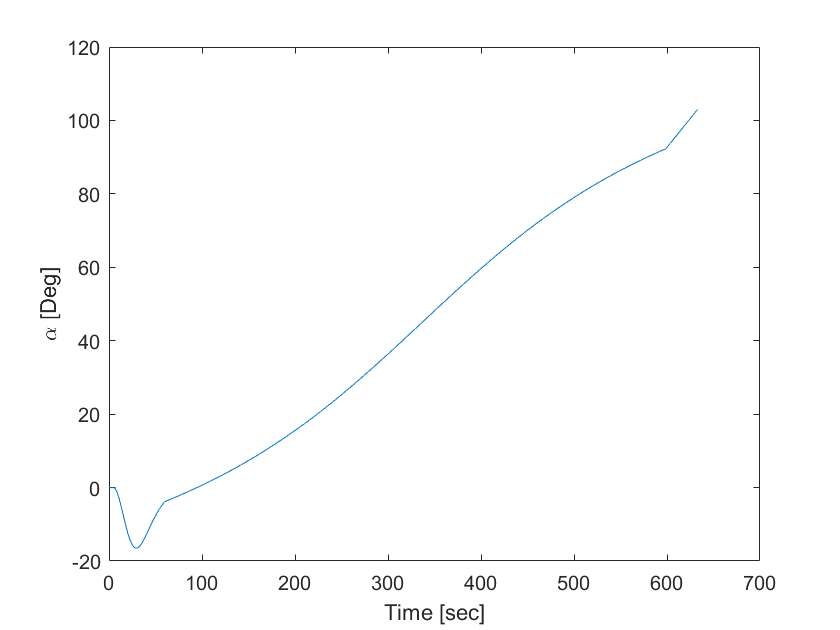

sim('SP2_Sim_SD2.slx');
% figure
plot(tout,Alpha_Sim);
xlabel('Time [sec]')
ylabel('\alpha [Deg]')

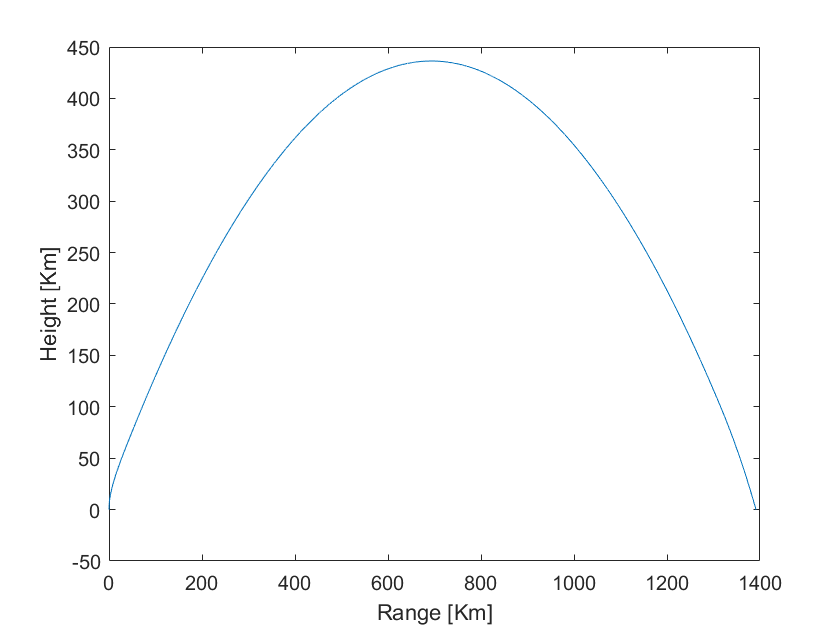


plot(X_Sim(:,1)/1e3,X_Sim(:,2)/1e3);
xlabel('Range [Km]')
ylabel('Height [Km]')


range=X_Sim(end,1)

range = 1.3914e+06


Mission_Cost=J_Sim(end)

Mission_Cost = -1.7354

## C

syms p(t) [4 1]
syms t_f t_0
T_Sim=5;
Sim=sim('SP2_Sim_a.slx');
X0=[X_Sim(end,1);X_Sim(end,2);X_Sim(end,3);X_Sim(end,4)]

X0 = 	1.0e+06 *

    1.3914
   -0.0000
    0.0020
   -0.0033


% syms m_p0 t_b m_0
% m(t)=-m_p0*t/t_b+m_0

## CC

J_c=-(x1(t_f)/1e6)^2

$$J\_c = -1.0000e-12\,{x_{1}\left(t_{f}\right)}^{2}$$

h=-(x1(t)/1e6)^2

$$h = -1.0000e-12\,{x_{1}\left(t\right)}^{2}$$

Ham=p.'*b     

$$Ham(t) = p_{1}\left(t\right)\,x_{3}\left(t\right)+p_{2}\left(t\right)\,x_{4}\left(t\right)+p_{4}\left(t\right)\,\left(\frac{\sin\left(u\left(t\right)\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-9.8100\right)+\frac{\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}$$

eq1=diff(p)==[-diff(Ham,x1);-diff(Ham,x2);-diff(Ham,x3);-diff(Ham,x4);]

eq1=simplify(eq1)

$$eq1(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}p_{1}\left(t\right)=0\\ \frac{\partial }{\partial t}p_{2}\left(t\right)=0\\ m\left(t\right)\,\left(\frac{\partial }{\partial t}p_{3}\left(t\right)+p_{1}\left(t\right)\right)=\mathrm{Drag}\,\left(\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)+\sin\left(u\left(t\right)\right)\,p_{4}\left(t\right)\right)\,\left(x_{4}\left(t\right)+2\,u\left(t\right)\,x_{3}\left(t\right)-2\,x_{3}\left(t\right)\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\\ m\left(t\right)\,\left(\frac{\partial }{\partial t}p_{4}\left(t\right)+p_{2}\left(t\right)\right)=-\mathrm{Drag}\,\left(\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)+\sin\left(u\left(t\right)\right)\,p_{4}\left(t\right)\right)\,\left(x_{3}\left(t\right)-2\,u\left(t\right)\,x_{4}\left(t\right)+2\,x_{4}\left(t\right)\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right) \end{array}\right)$$

eq2=0==diff(Ham,u)

$$eq2(t) = 0=p_{4}\left(t\right)\,\left(\frac{\cos\left(u\left(t\right)\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-\frac{\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)}{m\left(t\right)}\right)-\frac{\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-\frac{\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)}{m\left(t\right)}$$

eq2=simplifyFraction(eq2)

$$eq2(t) = 0=-\frac{\sin\left(u\left(t\right)\right)\,T\left(t\right)\,p_{3}\left(t\right)-\cos\left(u\left(t\right)\right)\,T\left(t\right)\,p_{4}\left(t\right)+\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,{x_{3}\left(t\right)}^{2}+\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,{x_{4}\left(t\right)}^{2}+\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,{x_{3}\left(t\right)}^{2}+\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,{x_{4}\left(t\right)}^{2}+\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,u\left(t\right)\,{x_{3}\left(t\right)}^{2}+\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,u\left(t\right)\,{x_{4}\left(t\right)}^{2}-\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,{x_{3}\left(t\right)}^{2}\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)-\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,{x_{4}\left(t\right)}^{2}\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)-\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,u\left(t\right)\,{x_{3}\left(t\right)}^{2}-\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,u\left(t\right)\,{x_{4}\left(t\right)}^{2}+\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,{x_{3}\left(t\right)}^{2}\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)+\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,{x_{4}\left(t\right)}^{2}\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)}{m\left(t\right)}$$


eq3=Ham(t_f)==-subs(diff(h,t),t,t_f)

$$eq3 = p_{1}\left(t_{f}\right)\,x_{3}\left(t_{f}\right)+p_{2}\left(t_{f}\right)\,x_{4}\left(t_{f}\right)+p_{4}\left(t_{f}\right)\,\left(\frac{\sin\left(u\left(t_{f}\right)\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}-9.8100\right)+\frac{\cos\left(u\left(t_{f}\right)\right)\,p_{3}\left(t_{f}\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}=2.0000e-12\,x_{1}\left(t_{f}\right)\,\frac{\partial }{\partial t_{f}}x_{1}\left(t_{f}\right)$$

eq3=Ham(t_f)==0

$$eq3 = p_{1}\left(t_{f}\right)\,x_{3}\left(t_{f}\right)+p_{2}\left(t_{f}\right)\,x_{4}\left(t_{f}\right)+p_{4}\left(t_{f}\right)\,\left(\frac{\sin\left(u\left(t_{f}\right)\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}-9.8100\right)+\frac{\cos\left(u\left(t_{f}\right)\right)\,p_{3}\left(t_{f}\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}=0$$

eq3=simplify(eq3);
eq3=isolate(eq3,p2(t_f))

$$eq3 = p_{2}\left(t_{f}\right)=-\frac{p_{1}\left(t_{f}\right)\,x_{3}\left(t_{f}\right)+p_{4}\left(t_{f}\right)\,\left(\frac{\sin\left(u\left(t_{f}\right)\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}-9.8100\right)+\frac{\cos\left(u\left(t_{f}\right)\right)\,p_{3}\left(t_{f}\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}}{x_{4}\left(t_{f}\right)}$$

eq4=[p1(t_f);p2(t_f);p3(t_f);p4(t_f)]==[subs(diff(h,x1),t,t_f);subs(rhs(eq3),[p3(t_f) p4(t_f)],[0 0]);subs(diff(h,x3),t,t_f);subs(diff(h,x4),t,t_f);];
eq4=simplify(eq4)

$$eq4(t) = \left(\begin{array}{c} p_{1}\left(t_{f}\right)=-2.0000e-12\,x_{1}\left(t_{f}\right)\\ p_{2}\left(t_{f}\right)=-\frac{p_{1}\left(t_{f}\right)\,x_{3}\left(t_{f}\right)}{x_{4}\left(t_{f}\right)}\\ p_{3}\left(t_{f}\right)=0\\ p_{4}\left(t_{f}\right)=0 \end{array}\right)$$

eq6=x2(t_f)==0

$$eq6 = x_{2}\left(t_{f}\right)=0$$

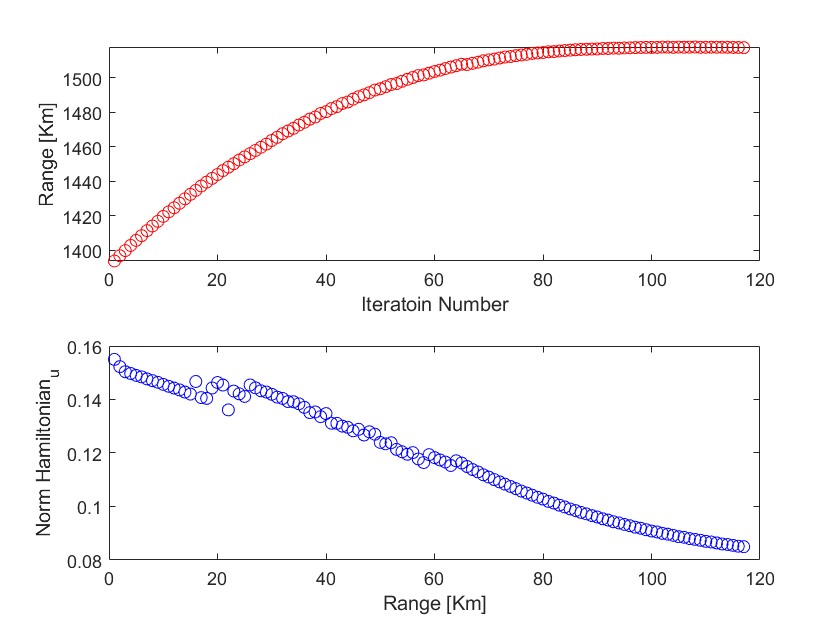


SD_Algorithm

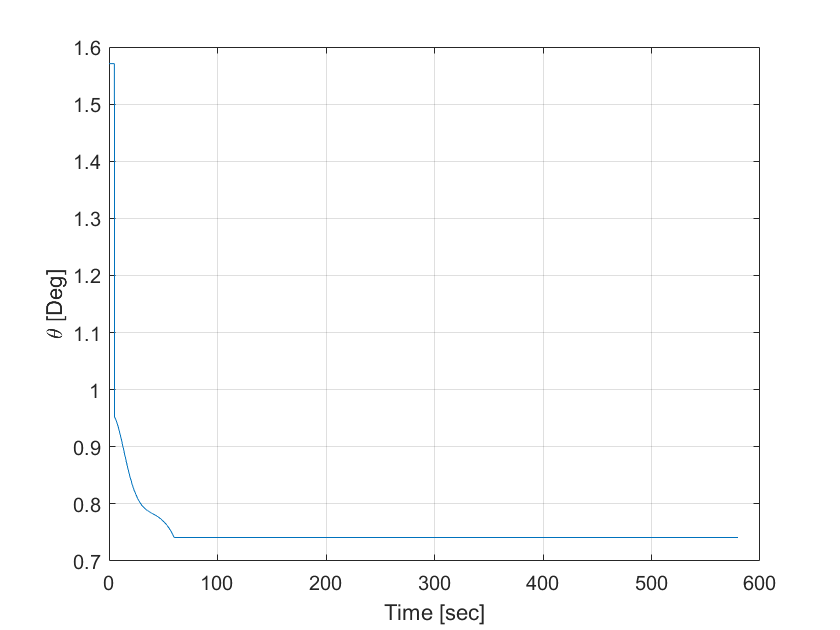


figure
plot(tout,U_Sim);
xlabel('Time [sec]')
ylabel('\theta [Deg]')
grid on

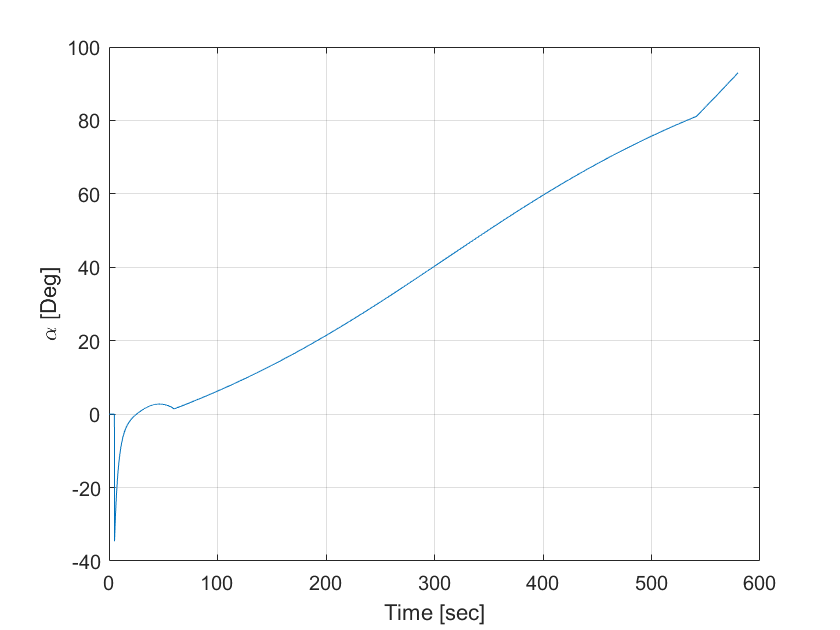

save('Theta_star_a.mat','U_Sim','tout')

plot(tout,Alpha_Sim);
xlabel('Time [sec]')
ylabel('\alpha [Deg]')
grid on

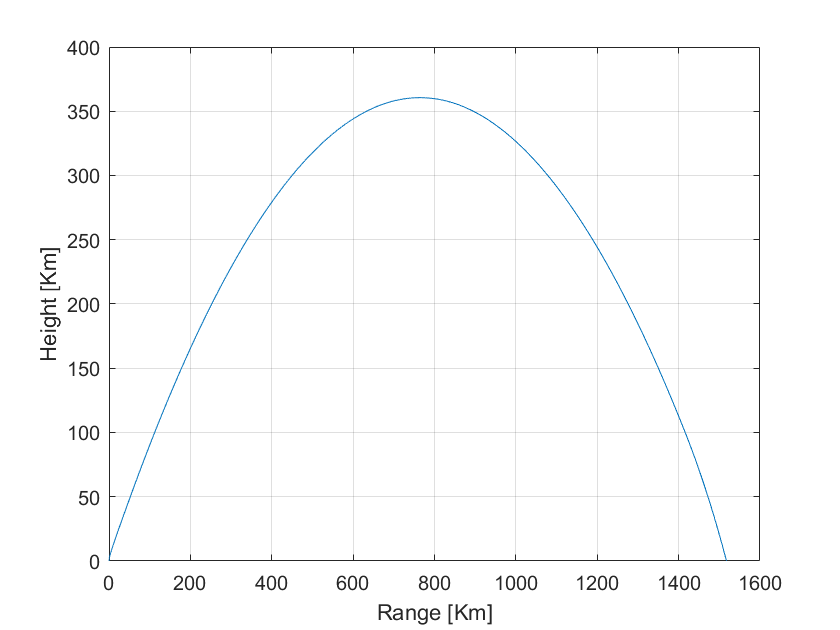


plot(X_Sim(:,1)/1e3,X_Sim(:,2)/1e3);
xlabel('Range [Km]')
ylabel('Height [Km]')
grid on


range=X_Sim(end,1)

range = 1.5176e+06


Mission_Cost=J_Sim(end)

Mission_Cost = -2.2192

## D

syms p(t) [4 1]
syms t x(t) [4 1]
syms T(t) rho CD_a u(t) S m(t) g theta(t) alpha(t)
h=-(x1(t)/1e6)^2

$$h = -1.0000e-12\,{x_{1}\left(t\right)}^{2}$$

J_D=h+0.1*int(alpha^2)

$$J\_D(t) = 0.1000\,\int {\alpha \left(t\right)}^{2}\mathrm{d}t-1.0000e-12\,{x_{1}\left(t\right)}^{2}$$

% u(t)-atan(x4/x3)
% syms alpha(u,x3,x4)
Ham=p.'*b+ (0.1*(u(t)-atan(x4/x3)))^2 

$$Ham(t) = {\left(0.1000\,u\left(t\right)-0.1000\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)}^{2}+p_{1}\left(t\right)\,x_{3}\left(t\right)+p_{2}\left(t\right)\,x_{4}\left(t\right)+p_{4}\left(t\right)\,\left(\frac{\sin\left(u\left(t\right)\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-9.8100\right)+\frac{\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}$$

% Ham=p.'*b+ (alpha)^2   

eq1=diff(p)==[-diff(Ham,x1);-diff(Ham,x2);-diff(Ham,x3);-diff(Ham,x4);]

eq1=simplify(eq1)

eq2=0==diff(Ham,u)

$$eq2(t) = 0=0.0200\,u\left(t\right)-0.0200\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)+p_{4}\left(t\right)\,\left(\frac{\cos\left(u\left(t\right)\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-\frac{\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)}{m\left(t\right)}\right)-\frac{\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,\left(T\left(t\right)-\mathrm{Drag}\,\left(u\left(t\right)-\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)\right)}{m\left(t\right)}-\frac{\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,\left({x_{3}\left(t\right)}^{2}+{x_{4}\left(t\right)}^{2}\right)}{m\left(t\right)}$$

eq2=simplifyFraction(eq2)

$$eq2(t) = 0=-\frac{0.0200\,\left(m\left(t\right)\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)-m\left(t\right)\,u\left(t\right)-50\,\cos\left(u\left(t\right)\right)\,T\left(t\right)\,p_{4}\left(t\right)+50\,\sin\left(u\left(t\right)\right)\,T\left(t\right)\,p_{3}\left(t\right)+50\,\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,{x_{3}\left(t\right)}^{2}+50\,\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,{x_{4}\left(t\right)}^{2}+50\,\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,{x_{3}\left(t\right)}^{2}+50\,\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,{x_{4}\left(t\right)}^{2}+50\,\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,u\left(t\right)\,{x_{3}\left(t\right)}^{2}+50\,\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,u\left(t\right)\,{x_{4}\left(t\right)}^{2}-50\,\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,{x_{3}\left(t\right)}^{2}\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)-50\,\mathrm{Drag}\,\cos\left(u\left(t\right)\right)\,p_{4}\left(t\right)\,{x_{4}\left(t\right)}^{2}\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)-50\,\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,u\left(t\right)\,{x_{3}\left(t\right)}^{2}-50\,\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,u\left(t\right)\,{x_{4}\left(t\right)}^{2}+50\,\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,{x_{3}\left(t\right)}^{2}\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)+50\,\mathrm{Drag}\,\sin\left(u\left(t\right)\right)\,p_{3}\left(t\right)\,{x_{4}\left(t\right)}^{2}\,\mathrm{atan}\left(\frac{x_{4}\left(t\right)}{x_{3}\left(t\right)}\right)\right)}{m\left(t\right)}$$


eq3=Ham(t_f)==-subs(diff(h,t),t,t_f)

$$eq3 = {\left(0.1000\,u\left(t_{f}\right)-0.1000\,\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)}^{2}+p_{1}\left(t_{f}\right)\,x_{3}\left(t_{f}\right)+p_{2}\left(t_{f}\right)\,x_{4}\left(t_{f}\right)+p_{4}\left(t_{f}\right)\,\left(\frac{\sin\left(u\left(t_{f}\right)\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}-9.8100\right)+\frac{\cos\left(u\left(t_{f}\right)\right)\,p_{3}\left(t_{f}\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}=2.0000e-12\,x_{1}\left(t_{f}\right)\,\frac{\partial }{\partial t_{f}}x_{1}\left(t_{f}\right)$$

eq3=Ham(t_f)==0

$$eq3 = {\left(0.1000\,u\left(t_{f}\right)-0.1000\,\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)}^{2}+p_{1}\left(t_{f}\right)\,x_{3}\left(t_{f}\right)+p_{2}\left(t_{f}\right)\,x_{4}\left(t_{f}\right)+p_{4}\left(t_{f}\right)\,\left(\frac{\sin\left(u\left(t_{f}\right)\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}-9.8100\right)+\frac{\cos\left(u\left(t_{f}\right)\right)\,p_{3}\left(t_{f}\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}=0$$

eq3=isolate(eq3,p2(t_f))

$$eq3 = p_{2}\left(t_{f}\right)=-\frac{{\left(0.1000\,u\left(t_{f}\right)-0.1000\,\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)}^{2}+p_{1}\left(t_{f}\right)\,x_{3}\left(t_{f}\right)+p_{4}\left(t_{f}\right)\,\left(\frac{\sin\left(u\left(t_{f}\right)\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}-9.8100\right)+\frac{\cos\left(u\left(t_{f}\right)\right)\,p_{3}\left(t_{f}\right)\,\left(T\left(t_{f}\right)-\mathrm{Drag}\,\left(u\left(t_{f}\right)-\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)\,\left({x_{3}\left(t_{f}\right)}^{2}+{x_{4}\left(t_{f}\right)}^{2}\right)\right)}{m\left(t_{f}\right)}}{x_{4}\left(t_{f}\right)}$$

eq4=[p1(t_f);p2(t_f);p3(t_f);p4(t_f)]==[subs(diff(h,x1),t,t_f);subs(rhs(eq3),[p3(t_f) p4(t_f)],[0 0]);subs(diff(h,x3),t,t_f);subs(diff(h,x4),t,t_f);]

$$eq4(t) = \left(\begin{array}{c} p_{1}\left(t_{f}\right)=-2.0000e-12\,x_{1}\left(t_{f}\right)\\ p_{2}\left(t_{f}\right)=-\frac{{\left(0.1000\,u\left(t_{f}\right)-0.1000\,\mathrm{atan}\left(\frac{x_{4}\left(t_{f}\right)}{x_{3}\left(t_{f}\right)}\right)\right)}^{2}+p_{1}\left(t_{f}\right)\,x_{3}\left(t_{f}\right)}{x_{4}\left(t_{f}\right)}\\ p_{3}\left(t_{f}\right)=0\\ p_{4}\left(t_{f}\right)=0 \end{array}\right)$$

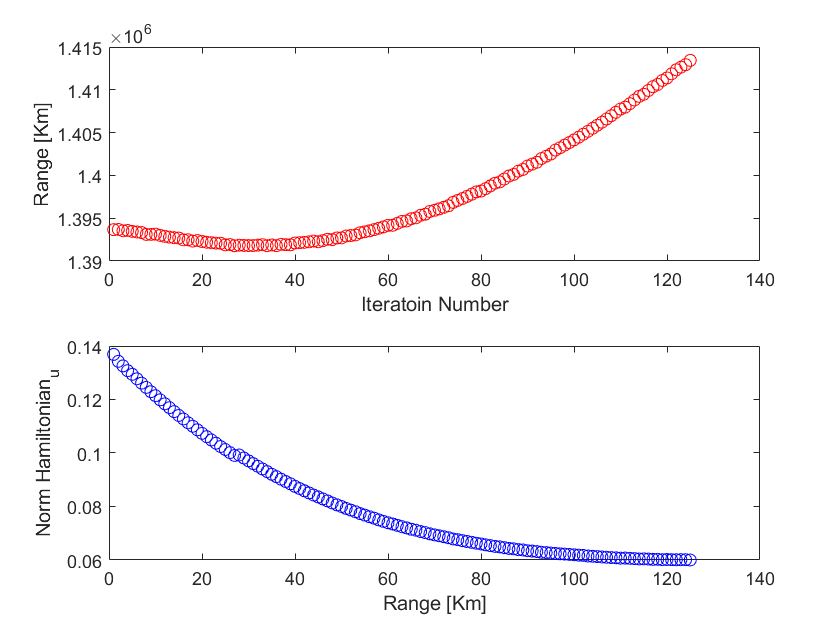



SD_Algorithm2

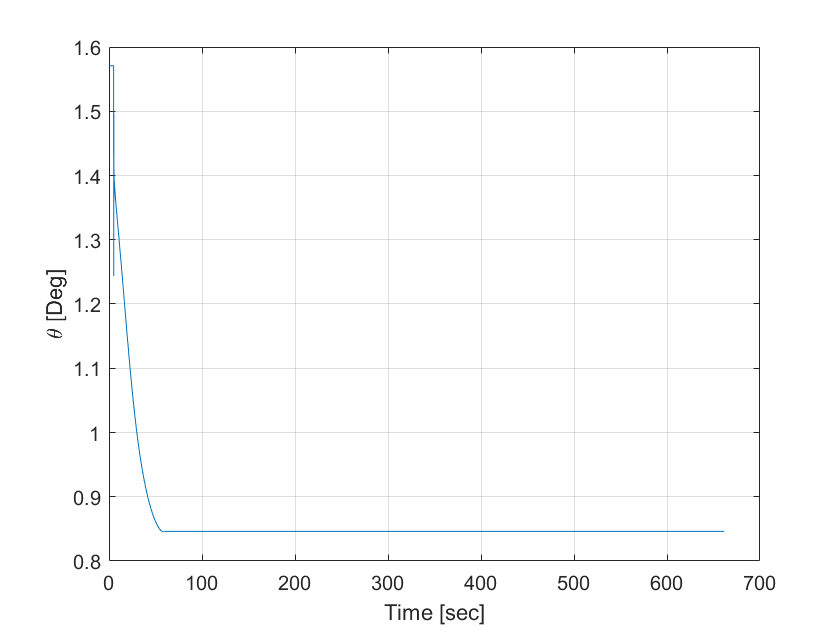


figure
plot(tout,U_Sim);
xlabel('Time [sec]')
ylabel('\theta [Deg]')
grid on

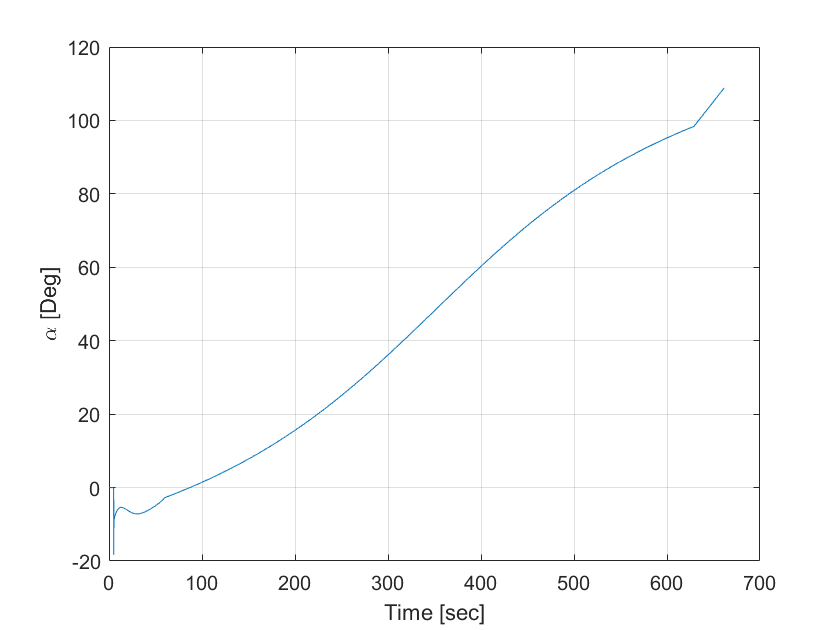


save('Theta_star_b.mat','U_Sim','tout')


plot(tout,Alpha_Sim);
xlabel('Time [sec]')
ylabel('\alpha [Deg]')
grid on

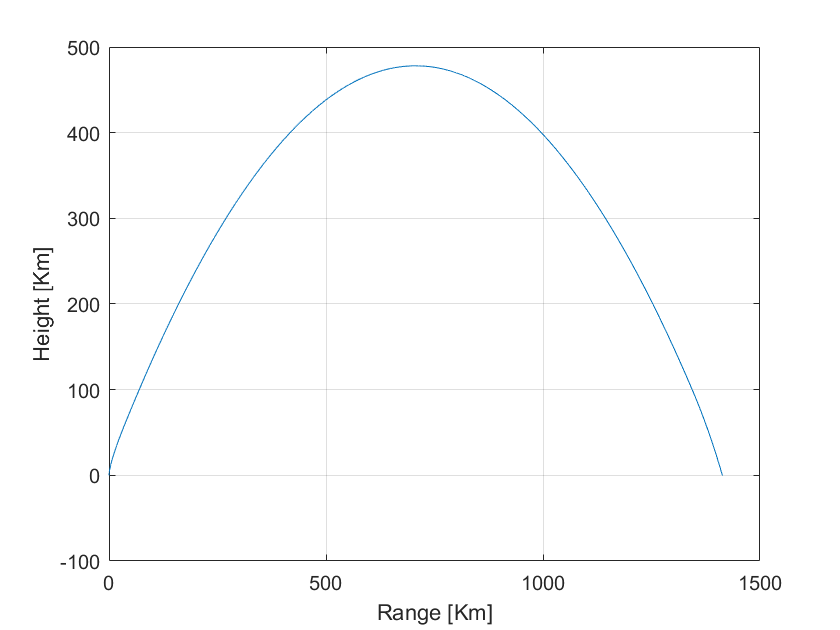


plot(X_Sim(:,1)/1e3,X_Sim(:,2)/1e3);
xlabel('Range [Km]')
ylabel('Height [Km]')
grid on


range=X_Sim(end,1)

range = 1.4134e+06


Mission_Cost=J_Sim(end)

Mission_Cost = -1.9358